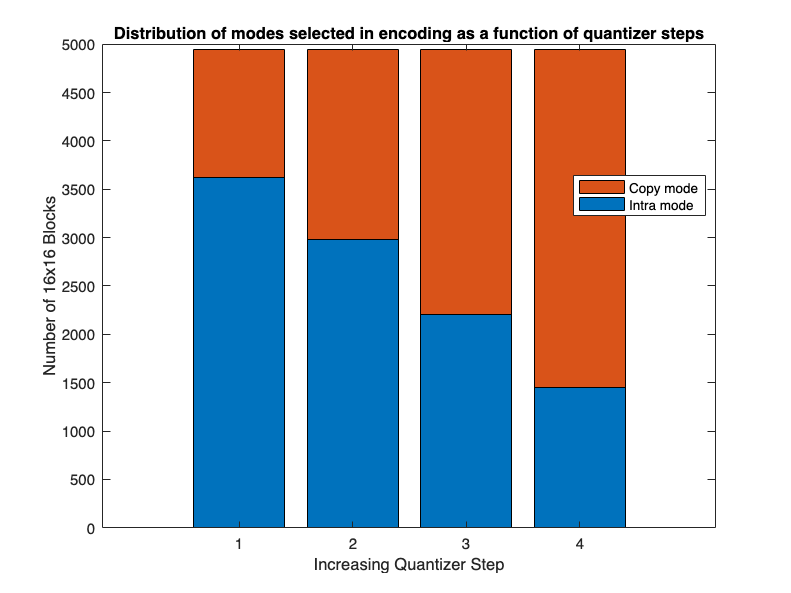

% Project 3
clear

% Function definitions
uniform_quantizer = @(x,ssize) round(x/ssize)*ssize;

% Set globals
video_width = 176;   %must be divisible by bSize
video_height = 144;  %must be divisible by bSize
FPS = 30;
Nframes = 50;  %to be imported

% Block Size for motion compensation
bSize = 16;
Nblocks = video_width*video_height/(bSize^2);
% Size of search space for the shifts. (same for negative and positive)
dy_max = 10;
dx_max = 10;
% Different step sizes for Quantization of Block-DCT coefficients
q_step = 2.^(3:6);

% Lagrange multiplier for optimization in choice of coding mode
% To be tuned so that DistortionCOst roughly == RateCost
lambda12 = 0.0005*q_step.^2;
lambda123 = 0.0003*q_step.^2;

% Compute all the possible shifts. For +- 10pxls there are 
% 441 possible motion vectors - 8bits needed without entropy coding.
index = 1;
n_vecs = (2*dy_max+1)*(2*dx_max+1);
shifts = zeros(2,n_vecs);
for i=-dy_max:dy_max
    for j=-dx_max:dx_max
        shifts(:,index) = [i,j];
        index = index+1;
    end
end

% import 50 frames of video
V = yuv_import_y('foreman_qcif.yuv',[video_width video_height],Nframes);
%V = yuv_import_y('mother-daughter_qcif.yuv',[video_width video_height],Nframes);

% deconstruct cell array
Frames = zeros(video_height,video_width,Nframes);
FramesPadded = zeros(video_height+2*dy_max,...
                     video_width+2*dx_max,Nframes);
for f=1:Nframes
    Frames(:,:,f) = V{f,1};
    % Pad with zeros around to handle the borders in the motion_vec_search
    FramesPadded(:,:,f) = padarray(Frames(:,:,f),[dy_max dx_max]);
end

FramesDCTq = zeros(video_height,video_width,Nframes,length(q_step));
Encoded1 = zeros(video_height,video_width,Nframes,length(q_step));
Err1f = zeros(Nframes,length(q_step));
PSNR1f = zeros(Nframes,length(q_step));
Rate1f = zeros(Nframes,length(q_step));
for f=1:Nframes
    %Intra frame only (mode 1)
    for q=1:length(q_step)
        FramesDCTq(:,:,f,q) = ...
            uniform_quantizer(blockproc(Frames(:,:,f),[8 8],@dctz2),q_step(q));
        Encoded1(:,:,f,q) = ...
            blockproc(FramesDCTq(:,:,f,q),[8 8],@idctz2);
        %Compute MSEs and PSNRs for mode 1
        Diff2 = (Encoded1(:,:,f,q) - Frames(:,:,f)).^2;
        Err1f(f,q) = sum(Diff2(:))/numel(Diff2(:));
        PSNR1f(f,q) = 10*log10( (255^2)/Err1f(f,q) );
        %Compute bits/coeff for mode 1
        Rate1f(f,q) = EntropyRate(FramesDCTq(:,:,f,q),q_step(q));
    end
end

Encoded2 = zeros(video_height,video_width,Nframes,length(q_step));
Err2f = zeros(Nframes,length(q_step));
PSNR2f = zeros(Nframes,length(q_step));
Rate2f = zeros(Nframes,length(q_step));

%rates (bits per block) for mode 2
R1 = mean(Rate1f,1)*bSize^2 + 1;        %intra mode
R2 = ones(1,length(q_step));            %copy mode

Rates = [R1;R2];

% Keep selected modes vector
Mode12 = zeros(Nblocks,Nframes,length(q_step));
Mode12(:,1,:) = 1;  % cannot copy the first frame

% Mode 2 - Conditional replenishment

Nbits2 = zeros(Nframes,q); %bits used for encoding of frame 
Nbits2(1,:) = R1*Nblocks;  %bits used for intra mode of 1st frame

% Set first frame to intra coded - since it is the only coding possible for
% the first frame
for q=1:length(q_step)
    Encoded2(:,:,1,q) = Encoded1(:,:,1,q);
end

for f=1:Nframes-1
    for q=1:length(q_step)
        ww = 1:bSize;
        hh = 1:bSize;
        bCount = 1;
       
        for h = 1:video_height/bSize
            for w = 1:video_width/bSize
                
                % For modes 1 and 2 distortions for encoding the next block
                Diff1 = (Frames(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1) - ...
                    Encoded1(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1,q)).^2;
                D1 = sum(Diff1(:))/numel(Diff1(:));
                Diff2 = (Frames(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1) - ...
                    Encoded2(bSize*(h-1)+hh,bSize*(w-1)+ww,f,q)).^2;
                D2 = sum(Diff2(:))/numel(Diff2(:));
                
                % Choose mode that minimizes Lagrangian cost
                Cost1 = D1 + lambda12(q)*R1(q); 
                Cost2 = D2 + lambda12(q)*R2(q);
                Costv = [Cost1,Cost2];
                [MinCost,ChosenMode] = min(Costv);
                
                % Save mode selected for visualizations and insight
                Mode12(bCount,f+1,q) = ChosenMode;
                % Accumulate Nbits used to get total Bits/Frame
                Nbits2(f+1,q) = Nbits2(f+1,q) + Rates(ChosenMode,q);
                
                % Encode video
                if ChosenMode == 1    %intra mode - set to Encoded1
                    Encoded2(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1,q) = ...
                        Encoded1(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1,q);
                elseif ChosenMode == 2  %copy block from previous frame
                    Encoded2(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1,q) = ...
                        Encoded2(bSize*(h-1)+hh,bSize*(w-1)+ww,f,q);
                end
                
                bCount = bCount + 1;
                
            end
        end
        
    end
end
clear Rates;
% Visualize Modes distribution for encoder (1+2)
mode_hist12 = zeros(length(q_step),2);
for q=1:length(q_step)
    mode_hist12(q,:) = hist(reshape(Mode12(:,:,q),1,numel(Mode12(:,:,q))),[1,2]);
end
figure;
bar(mode_hist12,'stacked');
title('Distribution of modes selected in encoding as a function of quantizer steps');
legend('Intra mode','Copy mode','location','best');
xlabel('Increasing Quantizer Step');
ylabel('Number of 16x16 Blocks');

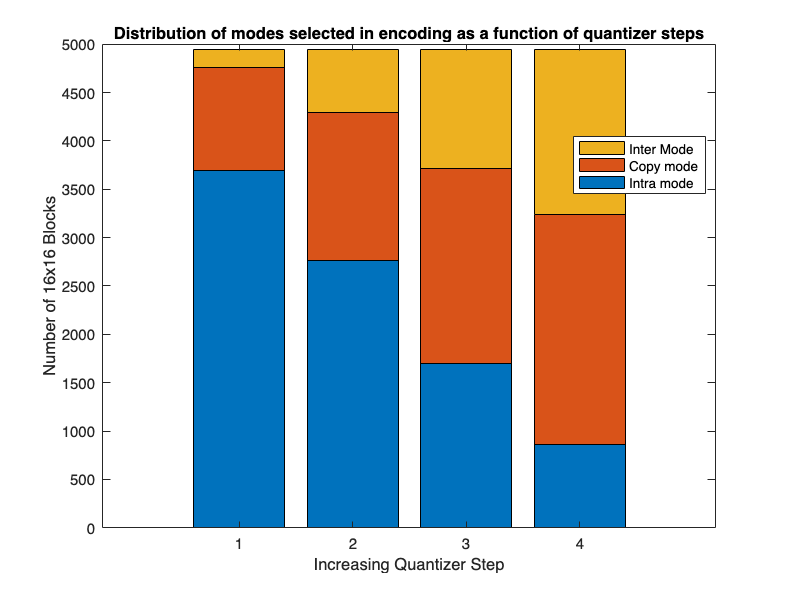


% Pad DCT quantized image, needed for computation of the motion compensated
% image
FramesPaddedq = zeros(video_height+2*dy_max,...
                     video_width+2*dx_max,Nframes,length(q_step));
for f=1:Nframes
    for q=1:length(q_step)
        % Pad with zeros around to handle the borders in the motion_vec_search
        FramesPaddedq(:,:,f,q) = ...
            padarray(Encoded1(:,:,f,q),[dy_max dx_max]);
    end
end

% Pre allocate memory
MotVecs = zeros(2,99,Nframes-1);
MotVecsIndices = zeros(1,99,Nframes-1);
% Use motion vectors to predict next frame and compute difference image
Predicted3 = zeros(video_height,video_width,Nframes); %mode 3 
Predicted3q = zeros(video_height,video_width,Nframes,length(q_step));
Residual = zeros(video_height,video_width,Nframes);
ResidualCopy = zeros(video_height,video_width,Nframes);
ResidualDCT = zeros(video_height,video_width,Nframes);
Residualq = zeros(video_height,video_width,Nframes,length(q_step));
ResidualDCTq = zeros(video_height,video_width,Nframes,length(q_step));
MotionCompq = zeros(video_height,video_width,Nframes,length(q_step));
%First frame cannot be predicted from past
Predicted3(:,:,1) = Frames(:,:,1);
for q=1:length(q_step)
    Predicted3q(:,:,1,q) = Encoded1(:,:,1,q);
end
for q=1:length(q_step)
    MotionCompq(:,:,1,q) = Encoded1(:,:,1,q);
end

Err2onlyf = zeros(Nframes,length(q_step));
PSNR2onlyf = zeros(Nframes,length(q_step));
Err3onlyf = zeros(Nframes,length(q_step));
PSNR3onlyf = zeros(Nframes,length(q_step));
Rate3onlyf = zeros(Nframes,length(q_step));


for f=1:Nframes-1   
    % Motion Compensation encoder (mode 3)
    % Compute motion vectors for all frames
    % Exaustive search implemented in ComputeMotVecs.m
    [MotVecs(:,:,f),MotVecsIndices(:,:,f)] = ...
        ComputeMotVecs(FramesPadded(:,:,f),Frames(:,:,f+1),bSize,shifts);
    Predicted3(:,:,f+1) = PredictFrame(FramesPadded(:,:,f),...
                                MotVecs(:,:,f),bSize,[dy_max dx_max]);
    Residual(:,:,f+1) =  Frames(:,:,f+1) - Predicted3(:,:,f+1);
    ResidualCopy(:,:,f+1) =  Frames(:,:,f+1) - Frames(:,:,f); 
    ResidualDCT(:,:,f+1) = blockproc(Residual(:,:,f+1),[8 8],@dctz2);
    
    % Estimate average bitrate needed for all motion vectors
    % motion vectors have usually low entropy, good for compression!
    p = hist(MotVecsIndices(:,:,f),n_vecs)./n_vecs;
    H = -sum(p.*log2(p+eps)); %bits/block
    rate_vecs = H/(bSize^2);   %bits/pixel
    
    %quantize residuals, with q_step in 4th dimension
    for q=1:length(q_step)
        Predicted3q(:,:,f+1,q) = PredictFrame(FramesPaddedq(:,:,f,q),...
                                MotVecs(:,:,f),bSize,[dy_max dx_max]);
                            
        ResidualDCTq(:,:,f+1,q) = ...
            uniform_quantizer(ResidualDCT(:,:,f+1),q_step(q));
        % Reconstruct with motion vectors and quantized residuals
        Residualq(:,:,f+1,q) = blockproc(ResidualDCTq(:,:,f,q),[8 8],@idctz2);
        MotionCompq(:,:,f+1,q) = Predicted3q(:,:,f+1,q) + Residualq(:,:,f+1,q);
    
        % Compute Error,PSNR for mode 2 (next - current quantized frame)
        Diff2 = (Frames(:,:,f+1)-Encoded1(:,:,f,q)).^2;
        Err2onlyf(f+1,q) = sum(Diff2(:))/numel(Diff2(:));
        PSNR2onlyf(f+1,q) = 10*log10( (255^2)/Err2onlyf(f+1,q) );
        % Rate2 for comparisons can be kept to zero, since the 2 bits to
        % signal the mode are needed for all 3 modes
        
        % Compute Error,PSNR for mode 3
        Diff2 = (MotionCompq(:,:,f+1,q)-Frames(:,:,f+1)).^2;
        Err3onlyf(f+1,q) = sum(Diff2(:))/numel(Diff2(:));
        PSNR3onlyf(f+1,q) = 10*log10( (255^2)/Err3onlyf(f+1,q) );
        
        % Compute Bitrate for mode 3 in bits/pixel
        rate_residual = EntropyRate(ResidualDCTq(:,:,f+1,q),q_step(q));
                        
        Rate3onlyf(f+1,q) = rate_vecs + rate_residual;  %bits/pxl mode 3
    end
end

%Now we have rates and errors for all frames. To simplify average all the
%rates and set the rate as a constant in the optimization of the Lagrangian
%function to choose mode   
AvgRate1 = (mean(Rate1f,1)*bSize^2 + 1);   %Bits/block
AvgRate3 = (mean(Rate3onlyf,1)*bSize^2 + 2);   %Bits/block

% Encoder3, with both copy conditional replenishment and motion compensation

% Rates per block are constants, to simplify
% +2 is added to signal the mode between the 3 available
% Rates are in Bits/block
R1 = mean(Rate1f,1)*bSize^2 + 2;        %intra mode
R2 = 2*ones(1,length(q_step));          %copy mode
R3 = mean(Rate3onlyf,1)*bSize^2 + 2;    %inter mode

Rates = [R1;R2;R3];

Mode123 = zeros(Nblocks,Nframes,length(q_step));
Mode123(:,1,:) = 1;  % cannot copy or inter code the first frame
Encoded3 = zeros(video_height,video_width,Nframes,length(q_step));
% Set first frame to intra coded - since it is the only coding possible for
% the first frame
for q=1:length(q_step)
    Encoded3(:,:,1,q) = Encoded1(:,:,1,q);
end
Nbits3 = zeros(Nframes,q);  %counts the bits used during the encoding
Nbits3(1,:) = R1*Nblocks;  %bits used for intra mode of 1st frame
% Loop over all frames and scan frames block by block
for f=1:Nframes-1 
    for q=1:length(q_step)
        
        %Pad to take into account edges in motion vectors
        %predictions
        Padded = padarray(Encoded3(:,:,f,q),[dy_max dx_max]);
        
        bCount = 1;
        ww = 1:bSize; %indices to get 16x16 blocks
        hh = 1:bSize;
        for h = 1:video_height/bSize
            for w = 1:video_width/bSize
                % For each mode, distortions for encoding the next block
                Diff1 = (Frames(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1) - ...
                    Encoded1(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1,q)).^2;
                D1 = sum(Diff1(:))/numel(Diff1(:));
                Diff2 = (Frames(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1) - ...
                    Encoded3(bSize*(h-1)+hh,bSize*(w-1)+ww,f,q)).^2;
                D2 = sum(Diff2(:))/numel(Diff2(:));
                
                
                
                % Compute motion compensated coordinates
                dy = MotVecs(1,bCount,f);
                dx = MotVecs(2,bCount,f);
                y_compensated = bSize*(h-1) + dy + hh + dy_max;
                x_compensated = bSize*(w-1) + dx + ww + dx_max;
                Diff3 = (Frames(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1) - ...
                    Padded(y_compensated,x_compensated)).^2;
                D3 = sum(Diff3(:))/numel(Diff3(:));    
                
                % Encode next block with the mode that minimizes the
                % Lagrangian cost
                Cost1 = D1 + lambda123(q)*R1(q); 
                Cost2 = D2 + lambda123(q)*R2(q);
                Cost3 = D3 + lambda123(q)*R3(q);
                % Select mode
                Costv = [Cost1,Cost2,Cost3];
                [MinCost,ChosenMode] = min(Costv);
                % Save mode history for visualization
                Mode123(bCount,f+1,q) = ChosenMode;
                % Accumulate Nbits used to get total Bits/Frame
                Nbits3(f+1,q) = Nbits3(f+1,q) + Rates(ChosenMode,q);
                
                % Encode video
                if ChosenMode == 1    %intra mode - set to Encoded1
                    Encoded3(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1,q) = ...
                        Encoded1(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1,q);
                elseif ChosenMode == 2  %copy block from previous frame
                    Encoded3(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1,q) = ...
                        Encoded3(bSize*(h-1)+hh,bSize*(w-1)+ww,f,q);
                else   %inter mode, take previous shifted block + residual
                    Encoded3(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1,q) = ...
                        Padded(y_compensated,x_compensated) + ...
                        Residualq(bSize*(h-1)+hh,bSize*(w-1)+ww,f+1,q);
                end
                
                bCount = bCount+1;
            end
        end
    end
end
% Visualize Modes distribution for the most complex encoder
mode_hist123 = zeros(length(q_step),3);
for q=1:length(q_step)
    mode_hist123(q,:) = hist(reshape(Mode123(:,:,q),1,numel(Mode123(:,:,q))),[1,2,3]);
end
figure;
bar(mode_hist123,'stacked');
title('Distribution of modes selected in encoding as a function of quantizer steps');
legend('Intra mode','Copy mode','Inter Mode','location','best');
xlabel('Increasing Quantizer Step');
ylabel('Number of 16x16 Blocks');

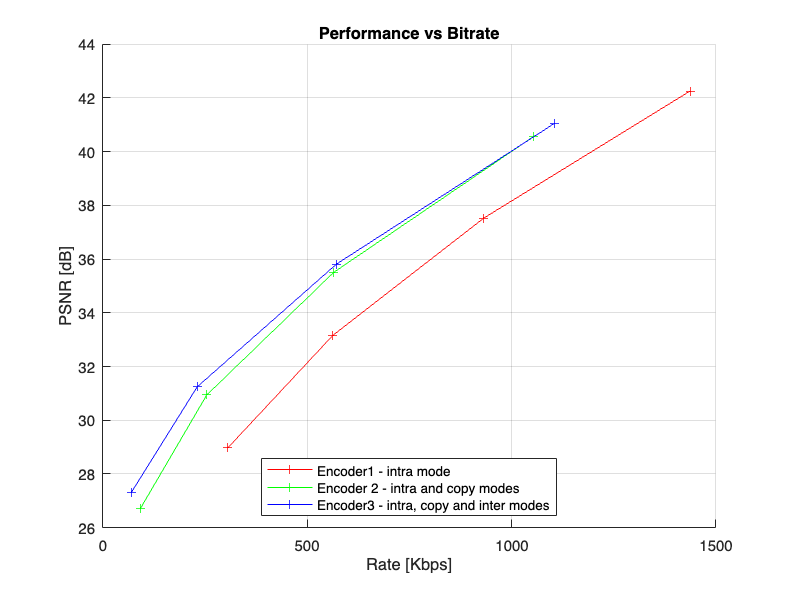


% Compute MSE and PSNR for encoder2 and encoder3
mse2 = zeros(1,length(q_step));
PSNR2 = zeros(1,length(q_step));
mse3 = zeros(1,length(q_step));
PSNR3 = zeros(1,length(q_step));
for q=1:length(q_step)   
        Diff_2 =  (Encoded2(:,:,:,q)-Frames).^2;
        mse2(1,q) = sum(Diff_2(:))/numel(Diff_2(:));
        PSNR2(1,q) = 10*log10(255^2/mse2(1,q));
    
        Diff_3 =  (Encoded3(:,:,:,q)-Frames).^2;
        mse3(1,q) = sum(Diff_3(:))/numel(Diff_3(:));
        PSNR3(1,q) = 10*log10(255^2/mse3(1,q));
end

% Compute bitrate for encoder2 and encoder3 in Kbps
RateKbps2 = mean(Nbits2,1)*30/1000;
RateKbps3 = mean(Nbits3,1)*30/1000;

%Compute avges for encoder1
PSNR1 = mean(PSNR1f,1);
RateKbps1 = mean(Rate1f,1)*video_height*video_width*30/1000;

% Mode 3 only
PSNR3only = mean(PSNR3onlyf,1);
RateKbps3only = mean(Rate3onlyf,1)*video_height*video_width*30/1000;

figure;
hold on
plot(fliplr(RateKbps1), fliplr(PSNR1),'r+-');
plot(fliplr(RateKbps2), fliplr(PSNR2),'g+-');
plot(fliplr(RateKbps3), fliplr(PSNR3),'b+-');
%plot(fliplr(RateKbps3only), fliplr(PSNR3only),'k+-');
title('Performance vs Bitrate');
grid on;
legend('Encoder1 - intra mode','Encoder 2 - intra and copy modes',...
    'Encoder3 - intra, copy and inter modes','location','best');
xlabel('Rate [Kbps]');
ylabel('PSNR [dB]');
hold off

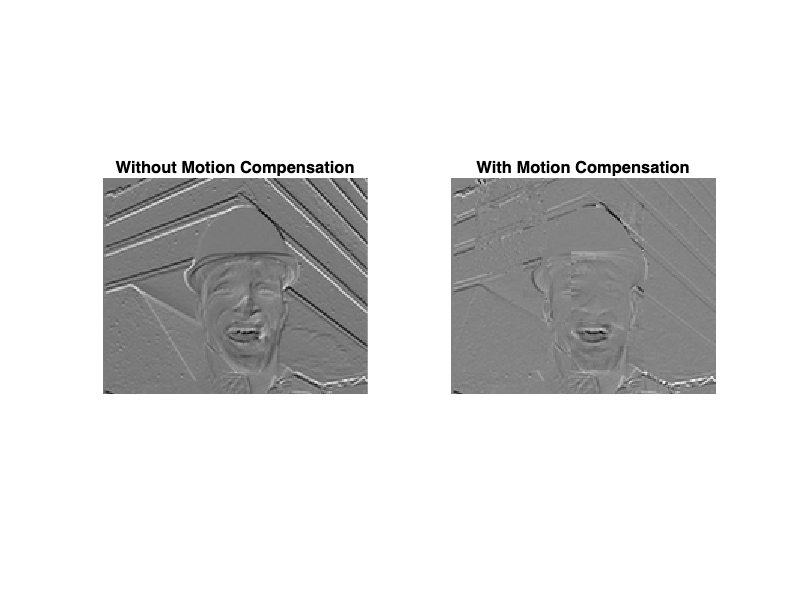


%Prepare Videos for writing
Framesw(:,:,1,:) = Frames;   %original
Residualw(:,:,1,:) = Residual;    %perfect residual
ResidualCopyw(:,:,1,:) = ResidualCopy;    %perfect residual
Residualqw(:,:,1,:,:) = Residualq;  %residual of mode 3
Predicted3qw(:,:,1,:,:) = Predicted3q; %mode 3 only without summing residuals
MotionCompqw(:,:,1,:,:) = MotionCompq;   %mode 3 only adding residuals
Encoded1w(:,:,1,:,:) = Encoded1; %intra mode only
Encoded2w(:,:,1,:,:) = Encoded2; %intra and copy
Encoded3w(:,:,1,:,:) = Encoded3; %All 3 modes available


%Compute energy of example residual at frame 23
residual_no_compensation = ResidualCopy(:,:,23);
residual = Residual(:,:,23);
energyr_no_compensation = sum(residual_no_compensation(:).^2);
energyr = sum(residual(:).^2);
figure;
subplot(1,2,1); imshow(residual_no_compensation,[]);
title('Without Motion Compensation');
subplot(1,2,2); imshow(residual,[]);
title('With Motion Compensation');